# Tropical Dynamics Toolbox - Demo

## Tropical Phase Portrait

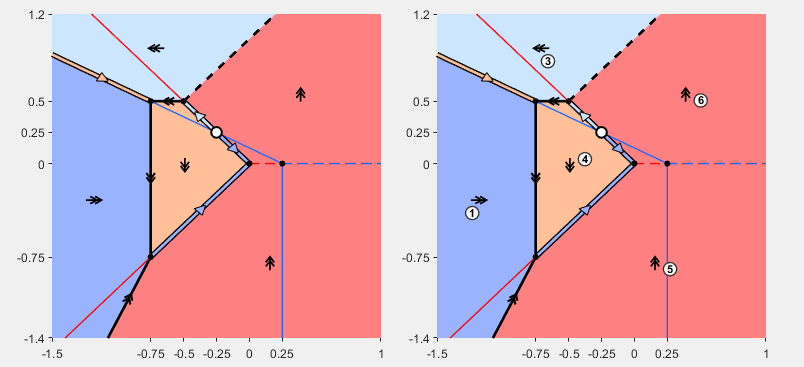

clc
clear
close all
% Tropical polynomials: [delta, alpha, n, m]
a = 0.25;
F = [1 a-1 -1 0;-1 -1 0 0; -1 -1 0 2];
G = [-1 0 0 0; 1 0 1 -1; 1 0 1 1];
% Phase plane without labels
figure("Visible","on","Units","normalized","OuterPosition",[0.2 0.2 .6 .6]);
tiledlayout(1,2,'Padding','compact','TileSpacing','compact')
nexttile
TropicalPhasePlane(F,G)
% Phase plane with labels
nexttile
TropicalPhasePlane(F,G,[],[],true)

## Simulated Trajectory

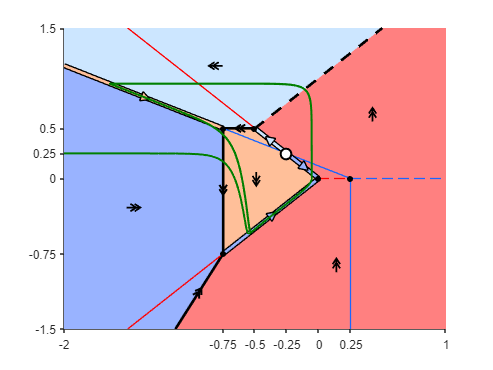

clc
clear
close all
a = 0.25;
F = [1 a-1 -1 0;-1 -1 0 0; -1 -1 0 2];
G = [-1 0 0 0; 1 0 1 -1; 1 0 1 1];
ulim = [-2 1];
vlim = [-1.5 1.5];
% Trajectory parameters
w0 = [ulim(1); 0.25];
eps = 0.08;
tspan = [0 exp(1/eps)];
% Plot phase plane with trajectory
figure
TropicalPhasePlane(F,G,ulim,vlim)
hold on
[T,W] = ode15s(@tropicalODE,tspan,w0,[],F,G,eps);
plot(W(:,1),W(:,2),'Color',[0 0.5 0],'LineWidth',1.5)

## Tropical Phase Portrait - Bifurcations

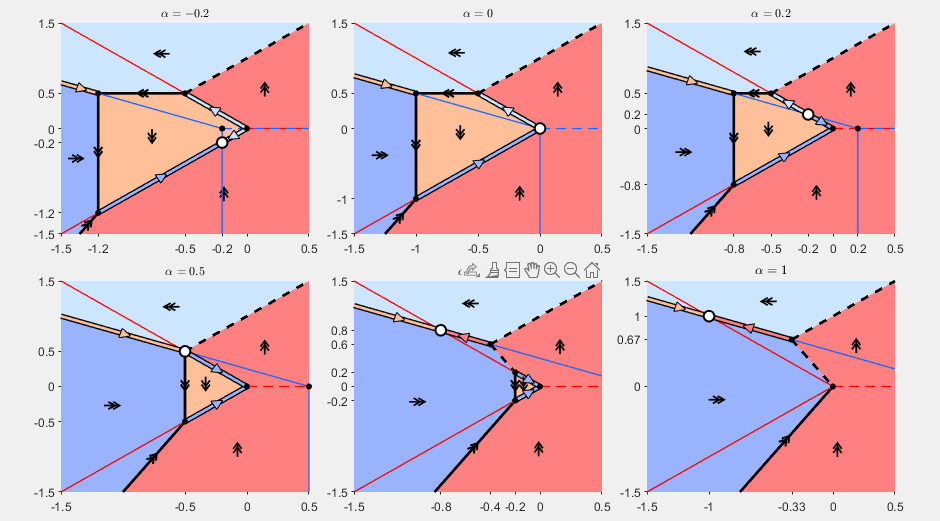

clc
clear
close all
figure("Visible","on","Units","normalized","OuterPosition",[0.1 0.1 .7 .8]);
A = [-0.2 0 0.2 0.5 0.8 1];
ulim = [-1.5 0.5];
vlim = [-1.5 1.5];
tiledlayout(2,3,"Padding","compact","TileSpacing","compact");
for a = A
    F = [1 a-1 -1 0;-1 -1 0 0; -1 -1 0 2];
    G = [-1 0 0 0; 1 0 1 -1; 1 0 1 1];
    nexttile
    TropicalPhasePlane(F,G,ulim,vlim)
    title("$\alpha = " + a + "$",'Interpreter',"latex")
end

## Tropical Phase Plane - All Quadrants

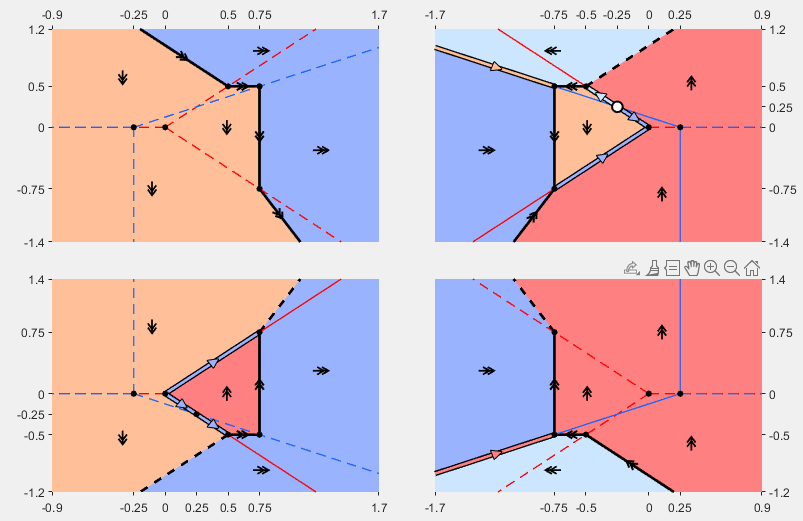

clc
clear
close all
figure("Visible","on","Units","normalized","OuterPosition",[0.1 0.1 .6 .8]);
a = 0.25;
F = [1 a-1 -1 0;-1 -1 0 0; -1 -1 0 2];
G = [-1 0 0 0; 1 0 1 -1; 1 0 1 1];
TropicalPhasePlaneAllQuadrants(F,G)

## Labelled Subdivision & Crossing Graph

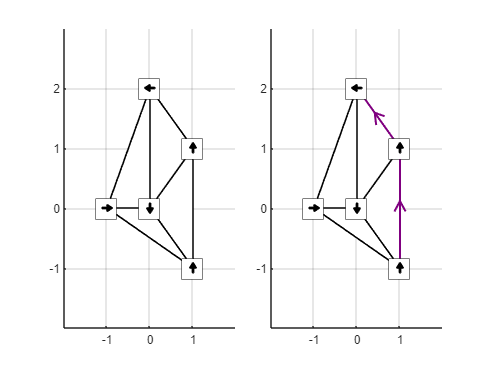

clc
clear
close all
a = 0;
F = [1 a-1 -1 0; -1 -1 0 0; -1 -1 0 2];
G = [-1 0 0 0; 1 0 1 -1; 1 0 1 1];
figure
tiledlayout(1,2,'TileSpacing','compact')
nexttile
LabelledSubdivision(F,G)
nexttile
CrossingGraph(F,G)

## Lifted Point Configuration

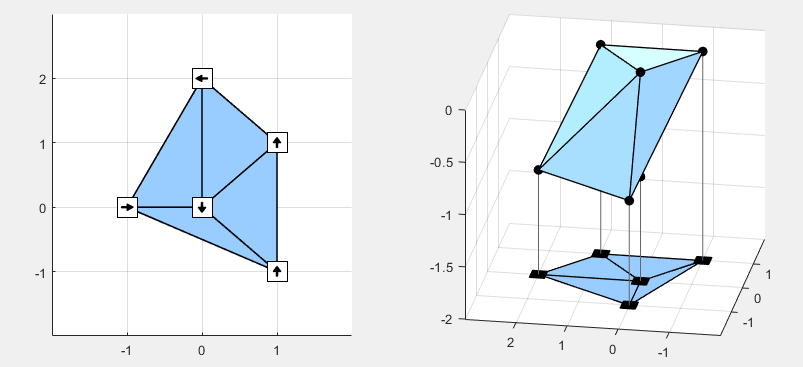

clc
clear
close all
a = 0;
F = [1 a-1 -1 0; -1 -1 0 0; -1 -1 0 2];
G = [-1 0 0 0; 1 0 1 -1; 1 0 1 1];
color = [0.6 0.8 1];
figure("Visible","on","Units","normalized","OuterPosition",[.1 .2 .6 .6]);
tiledlayout(1,2,"Padding","compact")
nexttile
LabelledSubdivision(F,G,'FaceColor',color)
nexttile
LiftedPointConfiguration(getPointsAndLabels(F,G),[],'FaceColor',color)

## Crossing Graph - Bifurcations

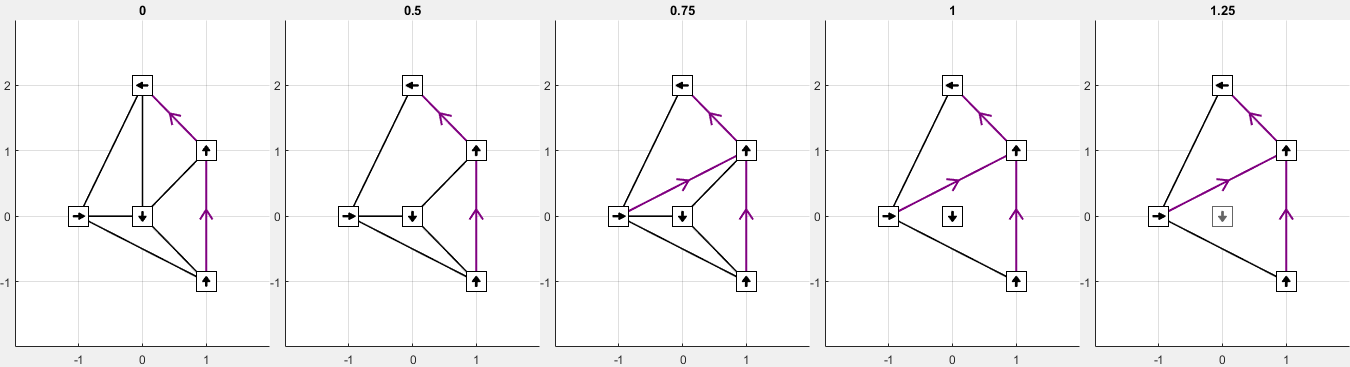

clc
clear
close all
A = [0 0.5 0.75 1 1.25];
color = [0.6 0.8 1];
figure("Visible","on","Units","normalized","OuterPosition",[0 0.2 1 .6]);
tiledlayout(1,5,'TileSpacing','tight','Padding','tight');
for a = A
    F = [1 a-1 -1 0; -1 -1 0 0; -1 -1 0 2];
    G = [-1 0 0 0; 1 0 1 -1; 1 0 1 1];
    nexttile
    CrossingGraph(F,G)
    title(a)
end

## Lifted Point Configuration - Bifurcations

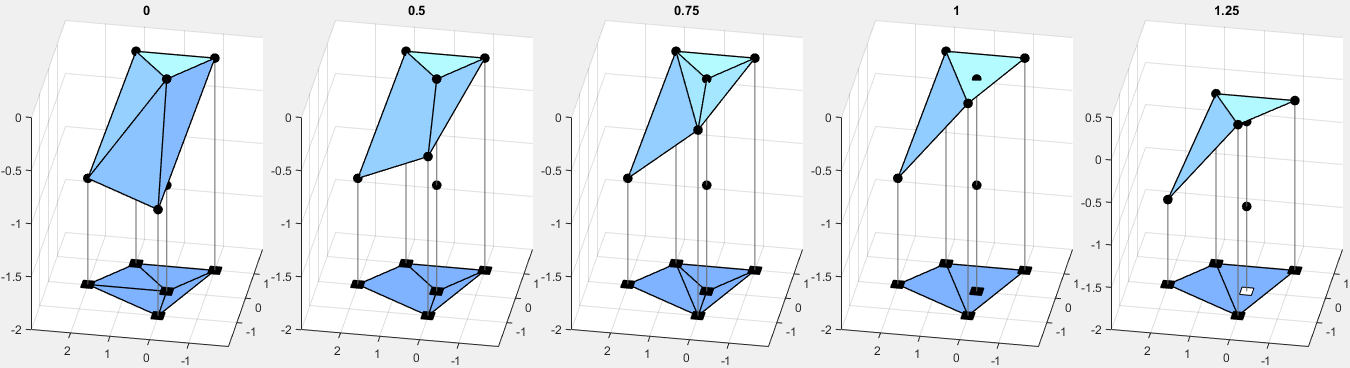

clc
clear
close all
A = [0 0.5 0.75 1 1.25];
figure("Visible","on","Units","normalized","OuterPosition",[0 0.1 1 .6]);
tiledlayout(1,5,'TileSpacing','tight','Padding','tight');
for a = A
    F = [1 a-1 -1 0; -1 -1 0 0; -1 -1 0 2];
    G = [-1 0 0 0; 1 0 1 -1; 1 0 1 1];
    nexttile
    LiftedPointConfiguration(getPointsAndLabels(F,G))
    title(a)
end

## Lifted Point Configuration - Minkowski Sum

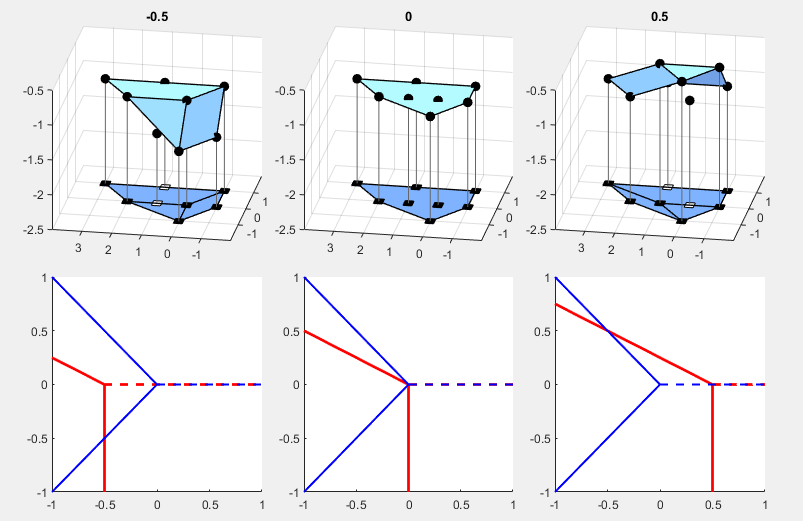

clc
clear
close all
A = [-0.5 0 0.5];
color = [0.6 0.8 1];
figure("Visible","on","Units","normalized","OuterPosition",[0.1 0.1 .6 .8]);
tiledlayout(2,3,'TileSpacing','compact','Padding','compact');
tile = 1;
for a = A
    F = [1 a-1 -1 0; -1 -1 0 0; -1 -1 0 2];
    G = [-1 0 0 0; 1 0 1 -1; 1 0 1 1];
    nexttile(tile)
    P = minkowskiSum(F(:,[3 4 2]), G(:,[3 4 2]));
    h0 = -2.5;
    LiftedPointConfiguration(P,h0)
    zlim([h0 -0.5])
    title(a)
    % Plot tropical nullclines
    nexttile(tile+3)
    ulim = [-1 1];
    TropicalCurve(TropicalDynamicalSystem(F,[]),ulim,ulim,'Color','red','LineWidth',2)
    hold on
    TropicalCurve(TropicalDynamicalSystem(G,[]),ulim,ulim,'Color','blue','LineWidth',1.5)
    tile = tile+1;
end